# BO6

Bender & Orszag page 181:


$$\begin{array}{l}
\dot{y_1 } =y_1^2 -y_1 y_2 -y_1 \\
\dot{y_2 } =y_2^2 +y_1 y_2 -2y_2 
\end{array}$$


clearvars; format long; addpath('functions/')

## Vector field lines

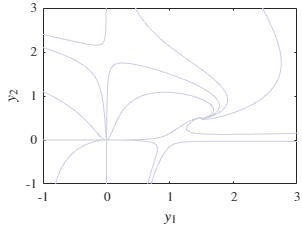


y0 = [1.49	0.495; 1.495 0.495; 1.5	0.5; 1.5 0.505; 1.505 0.495; 1.505 0.4925; 
      1.505 0.505; -1 0; -1 1.1; -1 2.1; -1 2.4;-0.8 -1; 0 -1; 0.65 -1; 0.7 -1];

Y_num{length(y0(:,1))} = {};
for i = 1:length(y0(:,1))
    [t_num,y_num] = ode78(@(t,y) ex6(t,y),[0 100],y0(i,:),odeset("Events",@stopInt,"RelTol",10^(-10),"AbsTol",10^(-10)));
    Y_num{i} = [t_num y_num];
end; clear y_num t_num i

figure; tiledlayout(1,1,"TileSpacing","tight","Padding","tight")
nexttile; hold on
for i = 1:length(y0(:,1)); plot(Y_num{i}(:,2),Y_num{i}(:,3),'Color',[0.8 0.8 0.9]); end
xlabel('$y_1$','Interpreter','latex'); ylabel('$y_2$','Interpreter','latex')
axis([-1 3 -1 3]); yticks([-2 -1 0 1 2 3]); xticks([-2 -1 0 1 2 3]);
set(gca,'FontSize',10,'TickLabelInterpreter','latex'); box on; clear i
set(gcf,'renderer','Painters','Units','centimeters','Position',[0 0 8 6]);

## Approximants

N = 2; syms a b t

### Around (0,0)

[A, Vars, x0] = MatA_ex6_eq1(N,a,b);  M = expm(A*t); X = formula(M*x0); lambda_00 = eig(A);
y1_eq1 = matlabFunction(X(Vars=='x10',:),'Vars',[t a b]); y2_eq1 = matlabFunction(X(Vars=='x01',:),'Vars',[t a b]); clear A Vars x0 X M

### Around (1,0)

[A, Vars, x0] = MatA_ex6_eq2(N,a,b);  M = expm(A*t); X = formula(M*x0); lambda_10 = eig(A);
y1_eq2 = matlabFunction(1+X(Vars=='x10',:),'Vars',[t a b]); y2_eq2 = matlabFunction(X(Vars=='x01',:),'Vars',[t a b]); clear A Vars x0 X M

### Around (0,2)

[A, Vars, x0] = MatA_ex6_eq3(N,a,b);  M = expm(A*t); X = formula(M*x0); lambda_02 = eig(A);
y1_eq3 = matlabFunction(X(Vars=='x10',:),'Vars',[t a b]); y2_eq3 = matlabFunction(2+X(Vars=='x01',:),'Vars',[t a b]); clear A Vars x0 X M

### Around (3/2,1/2)

[A, Vars, x0] = MatA_ex6_eq4(N,a,b);  M = expm(A*t); X = formula(M*x0); lambda_31 = eig(A);
y1_eq4 = matlabFunction(3/2+X(Vars=='x10',:),'Vars',[t a b]); y2_eq4 = matlabFunction(1/2+X(Vars=='x01',:),'Vars',[t a b]); clear A Vars x0 X M

## Plot preparation

Lim = 0.15;
y0eq1 = [ -0.5 0.5; -0.5 0; -0.5 -0.5; 0 -0.5; 0.5 -0.5; 0.5  0; 0.5  0.5; 0 0.5;
          -0.25 0.5; -0.25 -0.5; 0.25 -0.5; 0.25  0.5; -0.5 0.25; -0.5 -0.25];
[Yeq1_plot,Yeq1_teo_plot,isPlot_eq1] = distLim_plot_BO6(y0eq1,y1_eq1,y2_eq1,Lim);

y0eq2 = [0.65 -0.3; 0.5 -0.5; 1 -0.35; 1.25 -0.5; 1.4 0.25; 1.15 0.33; 1.2 0.1; 0.85 0.25];
[Yeq2_plot,Yeq2_teo_plot,isPlot_eq2] = distLim_plot_BO6(y0eq2,y1_eq2,y2_eq2,Lim);

y0eq3 = [0.10 2.20; 0.10 1.80; 0.50 1.50; 0.50 2.00; 1.00 2.00; -0.5 1.5; -0.2 2.25; -0.5 2.55; -0.2 2; -0.2 1.7; 0.8 1.85];
[Yeq3_plot,Yeq3_teo_plot,isPlot_eq3] = distLim_plot_BO6(y0eq3,y1_eq3,y2_eq3,Lim);

y0eq4 = [1.49 0.49; 1.49 0.495; 1.49 0.5; 1.495	0.495; 1.5 0.5; 1.5	0.505; 1.505 0.495; 1.505 0.4925; 1.505	0.505; 1.51	0.5];  
[Yeq4_plot,Yeq4_teo_plot,isPlot_eq4] = distLim_plot_BO6(y0eq4,y1_eq4,y2_eq4,Lim);

## Results

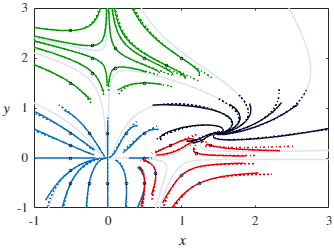

%%% Some plot options %%%%
grey = [0.854901960784314,0.890196078431373,0.949019607843137]; green = [0,0.600000000000000,0.003921568627451];
blue = [0.007843137254902,0.439215686274510,0.752941176470588]; color4 = [0.035294117647059,0.050980392156863,0.215686274509804];
red = [0.917647058823529,0,0.015686274509804];dotSize = 5; fontSize = 10; black = [0.035294117647059,0.050980392156863,0.215686274509804];
alpha_C = 0.9; alpha_teo = 0.85; lineWidth_teo = 1.15; lineWidth = 1.15; lineStyle_teo = ":";
%%%%%%%%%%%%%%%%%%%%%%%%%%

figure; tiledlayout(1,1,"TileSpacing","tight","Padding","tight")
nexttile; hold on
for i = 1:length(y0(:,1)); plot(Y_num{i}(:,2),Y_num{i}(:,3),'Color',grey,'LineWidth',lineWidth_teo); end
for i = 1:length(y0eq1(:,1))
    plot(Yeq1_plot{i}(:,2),Yeq1_plot{i}(:,3),'LineWidth',lineWidth,'Color',[blue alpha_C]);
    plot(Yeq1_teo_plot{i}(:,2),Yeq1_teo_plot{i}(:,3),'LineStyle',lineStyle_teo,'Color',[blue alpha_teo],'LineWidth',lineWidth);
    scatter(y0eq1(i,1),y0eq1(i,2),'o','CData',black,'SizeData',dotSize)
end
for i = 1:length(y0eq2(:,1))
    plot(Yeq2_plot{i}(:,2),Yeq2_plot{i}(:,3),'LineWidth',lineWidth,'Color',[red alpha_C]);
    plot(Yeq2_teo_plot{i}(:,2),Yeq2_teo_plot{i}(:,3),'LineStyle',lineStyle_teo,'Color',[red alpha_teo],'LineWidth',lineWidth);
    scatter(y0eq2(i,1),y0eq2(i,2),'o','CData',black,'SizeData',dotSize)
end
for i = 1:length(y0eq3(:,1))
    plot(Yeq3_plot{i}(:,2),Yeq3_plot{i}(:,3),'LineWidth',lineWidth,'Color',[green alpha_C]);
    plot(Yeq3_teo_plot{i}(:,2),Yeq3_teo_plot{i}(:,3),'LineStyle',lineStyle_teo,'Color',[green alpha_teo],'LineWidth',lineWidth);
    scatter(y0eq3(i,1),y0eq3(i,2),'o','CData',black,'SizeData',dotSize)
end
for i = 1:length(y0eq4(:,1))
    plot(Yeq4_plot{i}(:,2),Yeq4_plot{i}(:,3),'LineWidth',lineWidth,'Color',[color4 alpha_C]);
    plot(Yeq4_teo_plot{i}(:,2),Yeq4_teo_plot{i}(:,3),'LineStyle',lineStyle_teo,'Color',[color4 alpha_teo],'LineWidth',lineWidth);
    scatter(y0eq4(i,1),y0eq4(i,2),5,'o','CData',black,'SizeData',dotSize)
end
xlabel('$x$','Interpreter','latex'); ylabel('$y$','Interpreter','latex','Rotation',0,'HorizontalAlignment','right','VerticalAlignment','middle')
axis([-1 3 -1 3]); yticks([-2 -1 0 1 2 3]); xticks([-2 -1 0 1 2 3]);
set(gca,'FontSize',fontSize,'TickLabelInterpreter','latex'); box on; clear i
set(gcf,'renderer','Painters','Units','centimeters','Position',[0,0,8.85,6.6]);